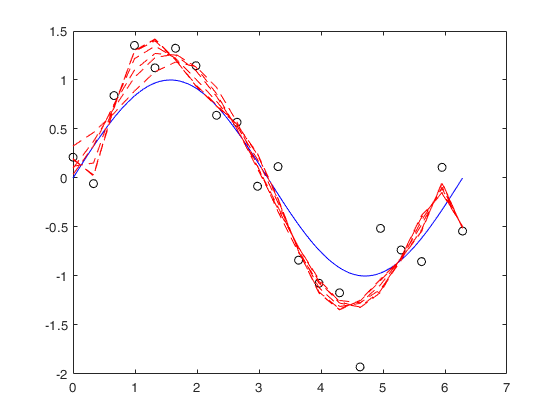

N = 20;                             % počet vzorků
func = @(x) sin(x);                 % testovaná funkce

x = 0:((2*pi)/(N-1)):2*pi;          % vzorkovací čas
t = awgn(func(x),10);               % naměřená data

x_c = 0:((2*pi)/((N*100)-1)):2*pi;  % spojitý čas
t_c = func(x_c);                    % spojitý průběh

M = 10;                              % řád polynomu

figure()
plot(x,t,'ko');                     % vykreslení naměřených dat
hold on;
plot(x_c,t_c,'b')                   % vykreslení původní funkce

% K = 20;
% E_RMS = zeros(1,K);
% E_RMS_c = zeros(1,K);
% for i = 0:K
%     
%     [t_w,w,~,E_w] = Polynomial_regression(x,t,i,0); % výpočet aproximace
%     E_RMS(i+1) = sqrt((2*E_w)/N);                   % výpočet chyby aproximace oproti naměřeným datům
% %     plot(x,t_w,'r--');                              % vykreselní aproximace
%     
%     t_w_c = Polynomial_evaluation(x_c,w);           % aplikace aproximace na testovací data
%     e_c = t_c - t_w_c;                              % rozdíly skutečných hodnot funkce oproti aproximaci
%     E_RMS_c(i+1) = sqrt((sum(e_c.^2))/(N*100));     % výpočet chyby aproximace oproti původním hodnotám funkce 
% end
% 
% figure();
% plot(0:K,E_RMS,'b-o');      % vykreslení vývoje chyb aproximace na TRÉNINKOVÝCH datech vůči velikosti prokládajícího polynomu 
% hold on;                
% plot(0:K,E_RMS_c,'r-o');    % vykreslení vývoje chyb aproximace na TESTOVACÍCH datech vůči velikosti prokládajícího polynomu


K = 10;
% asi rozmezí nula až jedna? takže t = 10^(x)
E_RMS = zeros(1,K);
E_RMS_c = zeros(1,K);
for i = -K:0
    
    [t_w,w,~,E_w] = Polynomial_regression(x,t,M,(10.^i));   % výpočet aproximace
    E_RMS(i+K+1) = sqrt((2*E_w)/N);                         % výpočet chyby aproximace oproti naměřeným datům
    plot(x,t_w,'r--');                                    % vykreselní aproximace
    
    t_w_c = Polynomial_evaluation(x_c,w);           % aplikace aproximace na testovací data
    e_c = t_c - t_w_c;                              % rozdíly skutečných hodnot funkce oproti aproximaci
    E_RMS_c(i+K+1) = sqrt((sum(e_c.^2))/(N*100));   % výpočet chyby aproximace oproti původním hodnotám funkce 
end

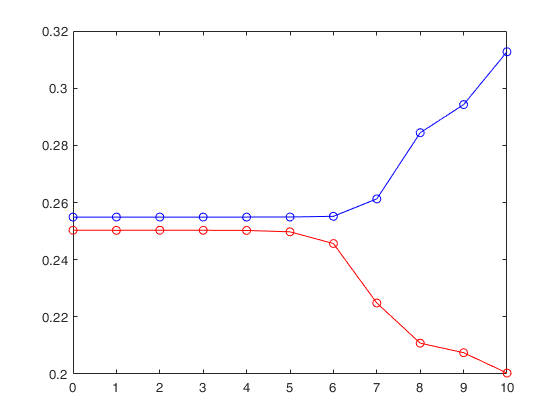


figure();
plot(0:K,E_RMS,'b-o');      % vykreslení vývoje chyb aproximace na TRÉNINKOVÝCH datech vůči velikosti prokládajícího polynomu 
hold on;                
plot(0:K,E_RMS_c,'r-o');    % vykreslení vývoje chyb aproximace na TESTOVACÍCH datech vůči velikosti prokládajícího polynomu